**A. Study of Sampling Frequency**

**Theory : **

- The speech signal sampled at 8 kHz is termed as narrowband speech and the speech signal sampled at 16 kHz is termed as wideband speech. 

- For practical speech signal processing, if the speech signal is available from a telephone or mobile channel, the sampling frequency 8 kHz is used, without option.

Alternatively, if the speech signal is available from a wideband channel, then 16 kHz sampling frequency is suggested. **The final proposal is 16 kHz is the optimal sampling frequency for speech.** Rest of the study about bit resolution is therefore performed using wideband speech.

- Record the word **‘Speech’** using a sampling frequency of **44.1kHz** save it in a .wav file. Plot the complete speech signal and the frequency spectrum for different sounds.

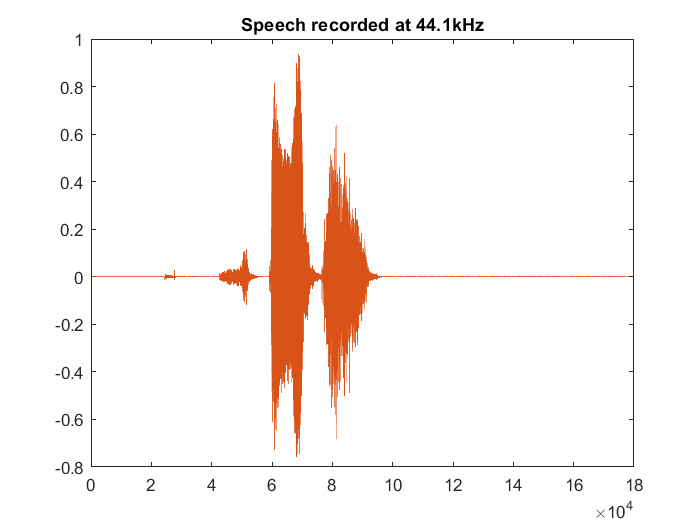

[y,Fs] = audioread('speech.wav');
sound(y,Fs);
figure();
plot(y);
title('Speech recorded at 44.1kHz');

%Frequency Spectrum for different sounds

## Sound: 'S'

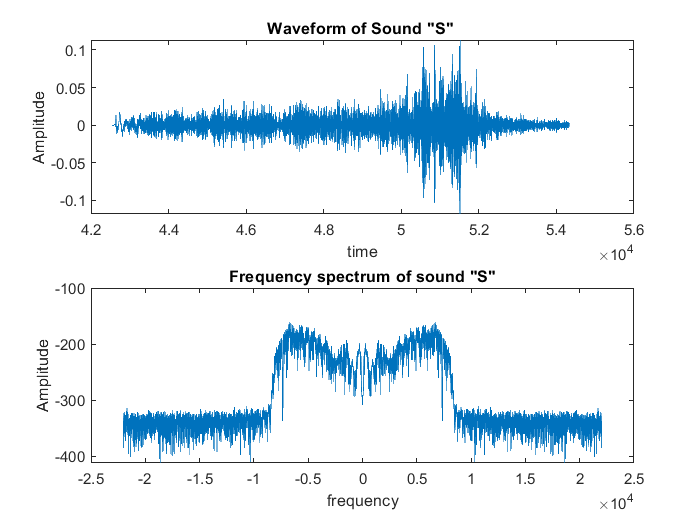

fs = 44100;
t1=0.965*fs : 1.232*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "S" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "S"');

## Sound: 'P'

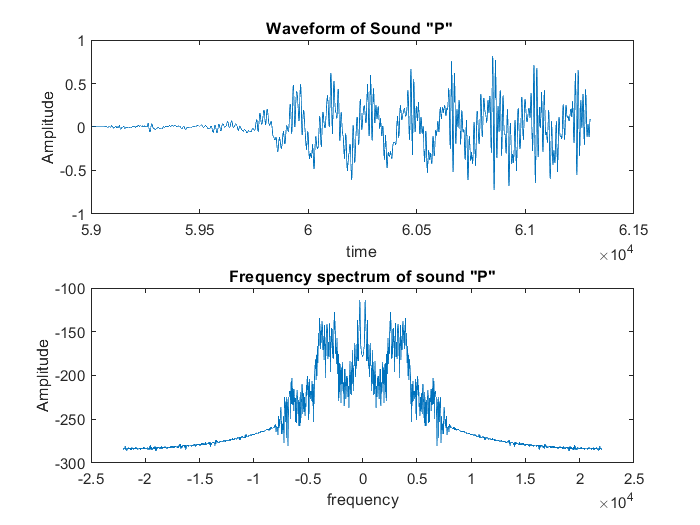

fs = 44100;
t1=1.338*fs : 1.390*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "P" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "P"');

## Sound: 'ee'

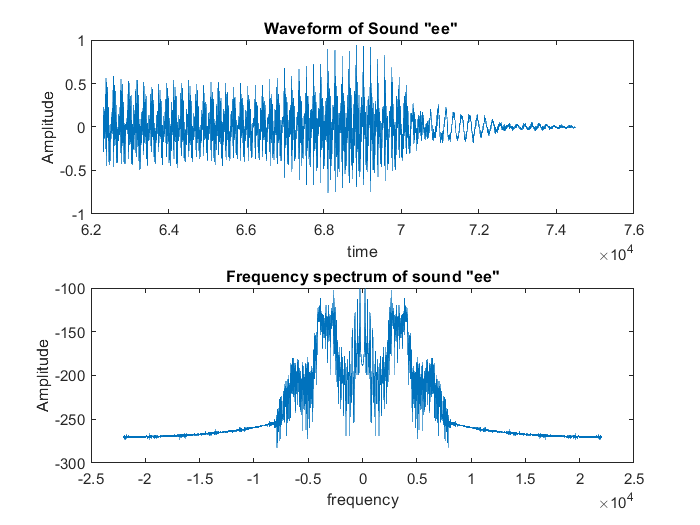

fs = 44100;
t1=1.413*fs : 1.689*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ee" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "ee"');

## Sound: 'ch'

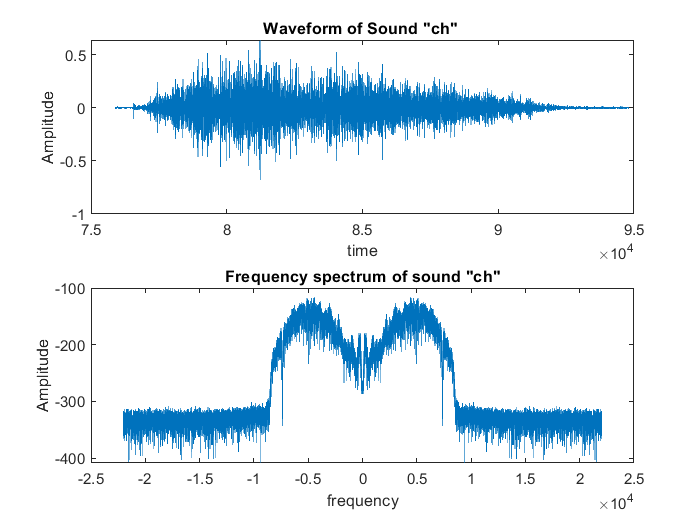

fs = 44100;
t1=1.721*fs : 2.150*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ch" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "ch"');

2. Resample to 16 kHz,

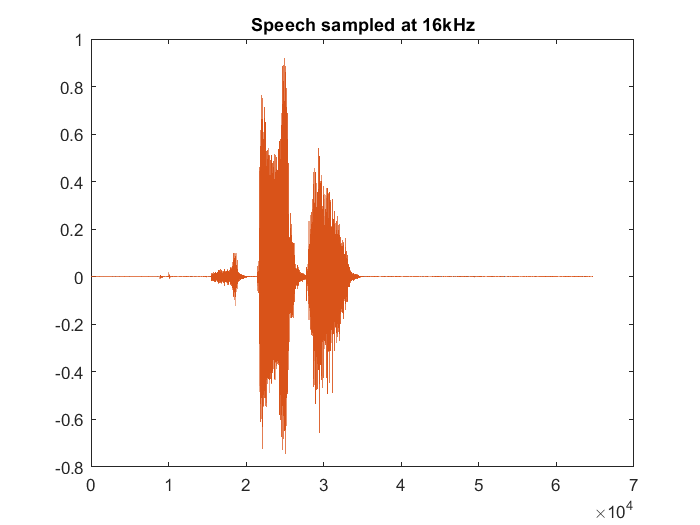

y1=resample(y,16000,Fs); 
figure();
plot(y1);
title('Speech sampled at 16kHz');

## Sound: 'S'

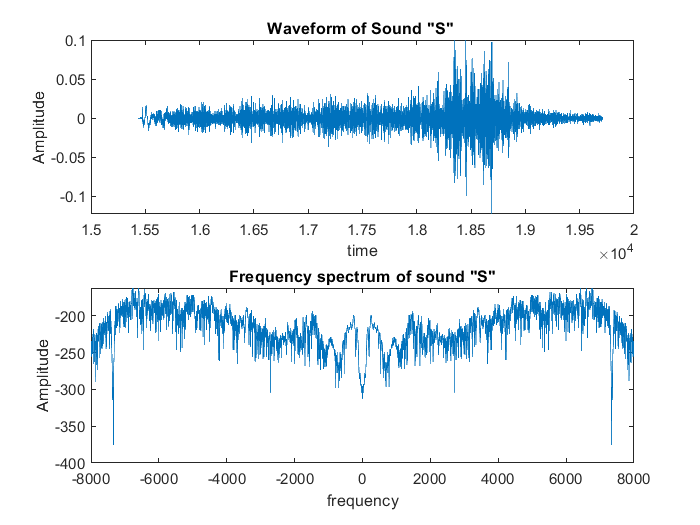

fs = 16000;
t1=0.965*fs : 1.232*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "S" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "S"');

## Sound: 'P'

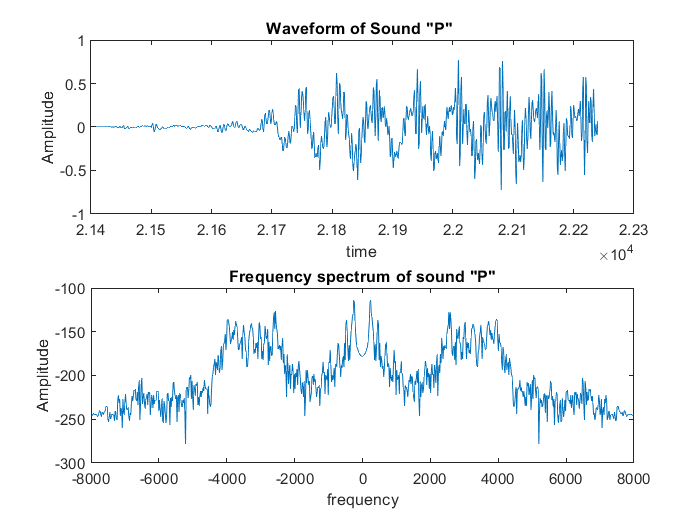

t1=1.338*fs : 1.390*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "P" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "P"');

## Sound: 'ee'

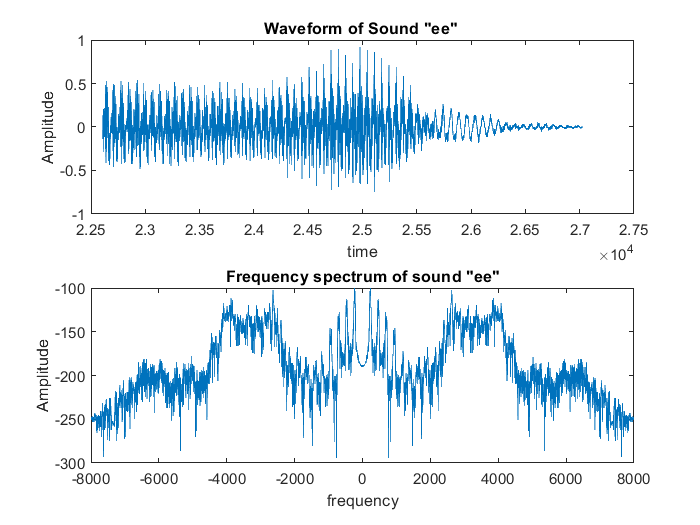

t1=1.413*fs : 1.689*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ee" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "ee"');

## Sound: 'ch'

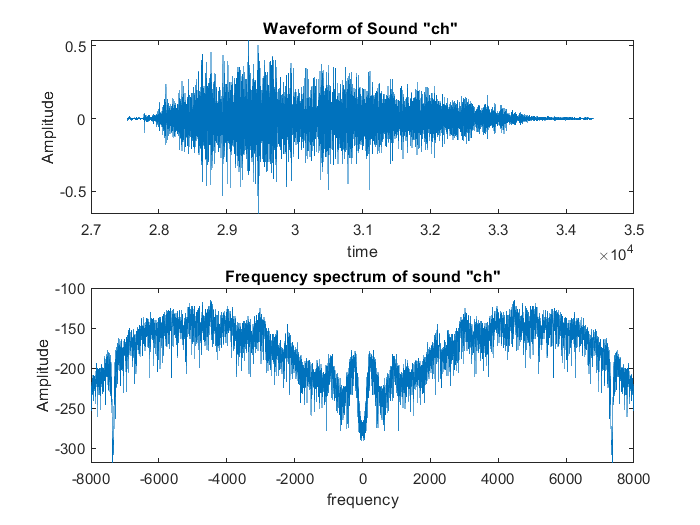

t1=1.721*fs : 2.150*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ch" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "ch"');

**Observations and comments : **

1) In case of sampling frequency conversion, by keeping the bit resolution same, the waveforms may not show much distinction for visual perception. The change can only be observed in terms of the frequency contents as illustrated in different spectra.

2) As it can be observed from different spectral fugures there are no significant frequency components in the spectrum beyond about 10 kHz. This observation shows that 44.1 kHz sampling is too high value to capture the information present in the speech signal.So, **the intelligibilty to choose 16kHz as sampling frequency was correct.**

3. Resample to 8kHz

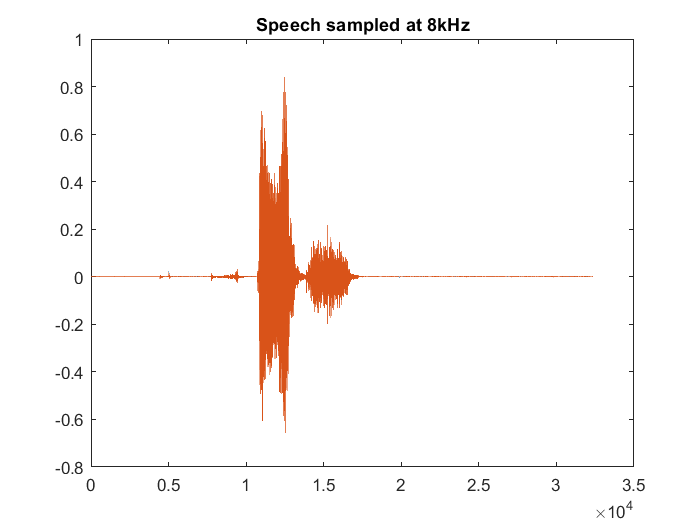

y1=resample(y,8000,Fs); 
figure();
plot(y1);
title('Speech sampled at 8kHz');

## Sound: 'S'

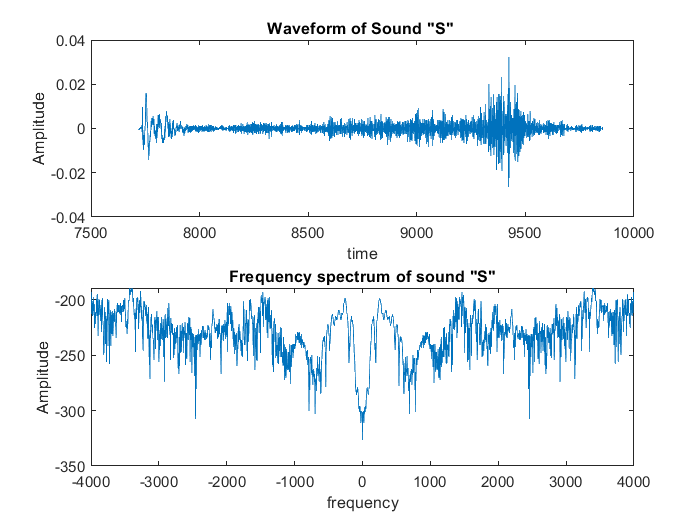

fs = 8000;
t1=0.965*fs : 1.232*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "S" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "S"');

## Sound: 'P'

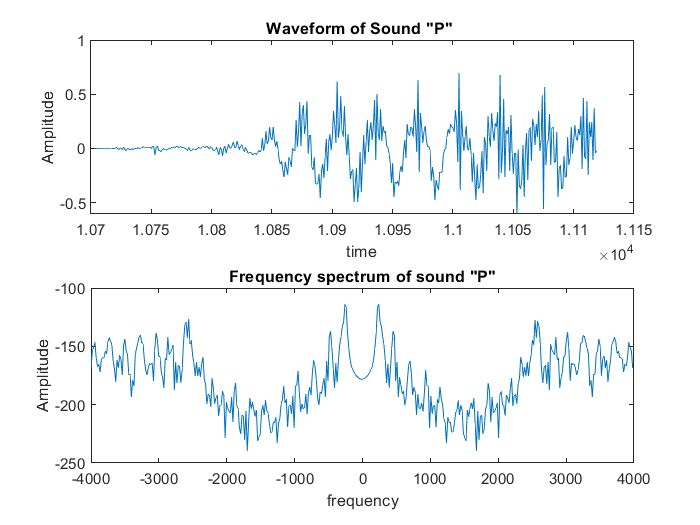

t1=1.338*fs : 1.390*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "P" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "P"');

## Sound: 'ee'

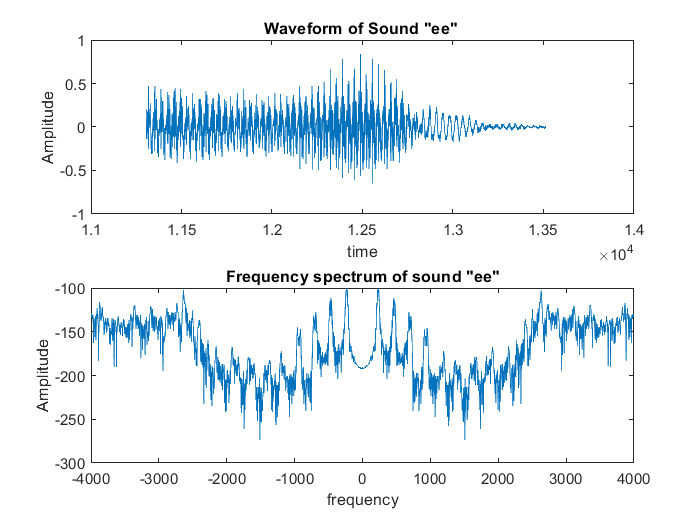

t1=1.413*fs : 1.689*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ee" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "ee"');

## Sound: 'ch'

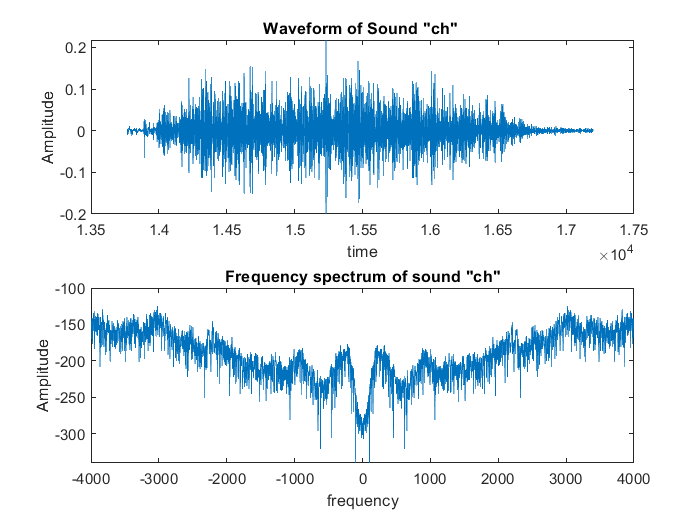

t1=1.721*fs : 2.150*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ch" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "ch"');

4. Resample to 4kHz

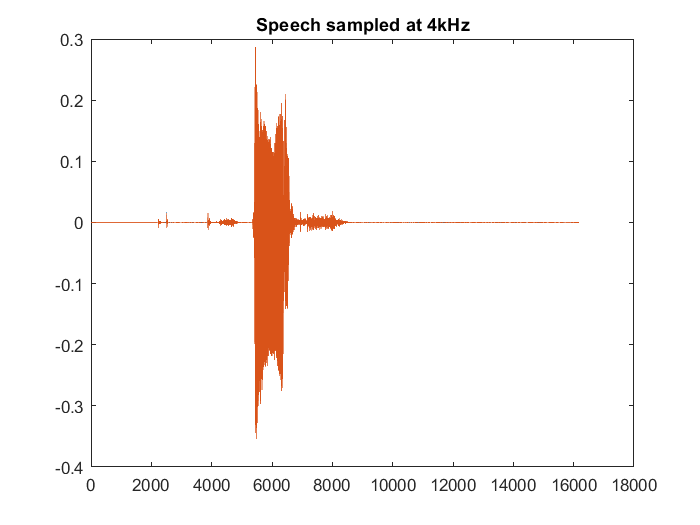

y1=resample(y,4000,Fs); 
figure();
plot(y1);
title('Speech sampled at 4kHz');

## Sound: 'S'

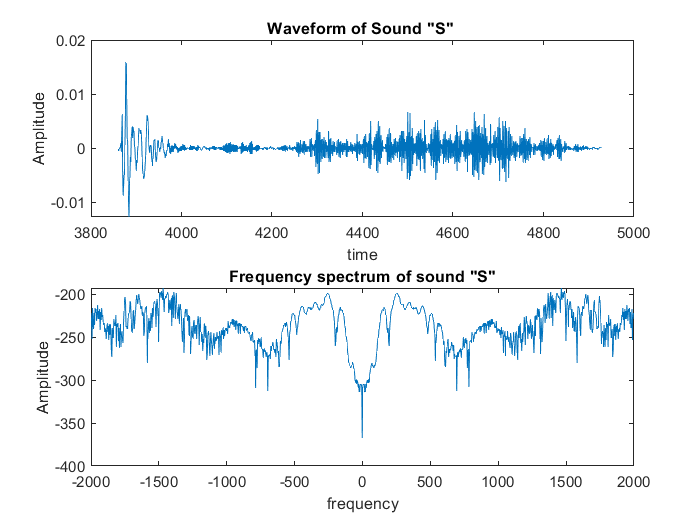

fs = 4000;
t1=0.965*fs : 1.232*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "S" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "S"');

## Sound: 'P'

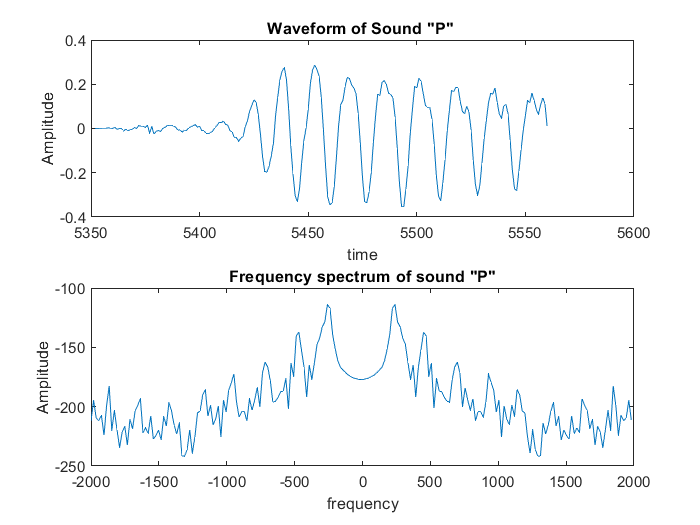

t1=1.338*fs : 1.390*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "P" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "P"');

## Sound: 'ee'

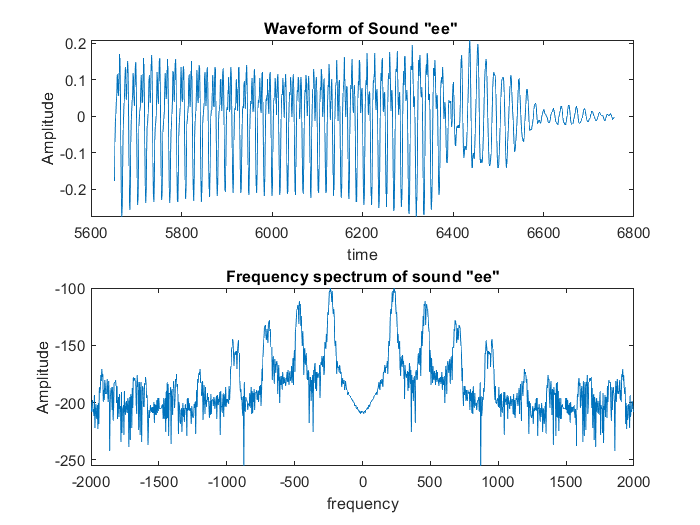

t1=1.413*fs : 1.689*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ee" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "ee"');

## Sound: 'ch'

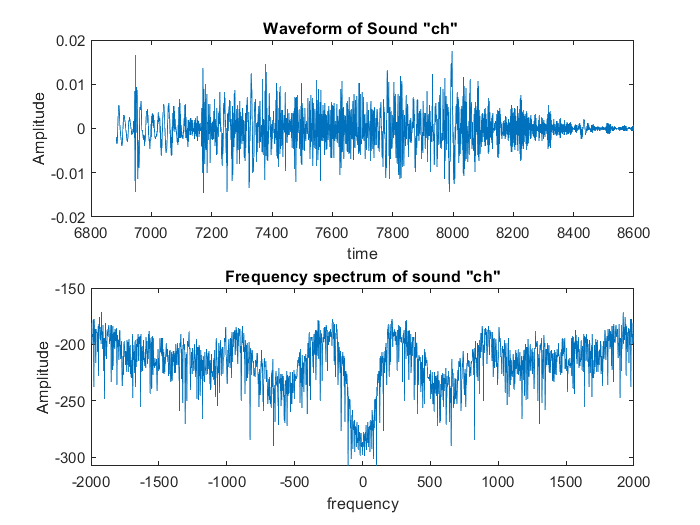

t1=1.721*fs : 2.150*fs ; % Time Observed From Wavesurfer
t1=round(t1);
x1=y1(t1);
dF1= fs/length(t1); % Time resolution for "a" sound
f1=-fs/2:dF1:fs/2-dF1 ; % hz pers sample
X1=fftshift(fft(x1)); % Fourier transform
figure();
subplot(2,1,1);
plot(t1,x1);
xlabel('time');
ylabel('Amplitude');
title('Waveform of Sound "ch" ');
subplot(2,1,2);
plot(f1,20*log(abs(X1)/fs));
xlabel('frequency');
ylabel('Amplitude');
title('Frequency spectrum of sound "ch"');

**Observations and comments : **

1) In case of sampling frequency conversion, by keeping the bit resolution same, the waveforms may not show much distinction for visual perception. The change can only be observed in terms of the frequency contents as illustrated in different spectra.

2) As it can be observed from different spectral fugures there are no significant frequency components in the spectrum beyond about 10 kHz. This observation shows that 44.1 kHz sampling is too high value to capture the information present in the speech signal.So, **the intelligibilty to choose 16kHz as sampling frequency was correct.**

3) As it can be observed from the frequency spectrum, most of the speech signal has frequency components only upto 8 kHz. Thus **16 kHz seems to be optimal sampling frequency for the case of speech.**

4) Choosing 8kHz and 4kHz is not very optimal to use as the frequency spectrum is getting lost towards the end.

**Conclusion :** 

16kHz is the optimal choice for sampling frequency for speech.